First the image is loaded and converted to grayscale. 

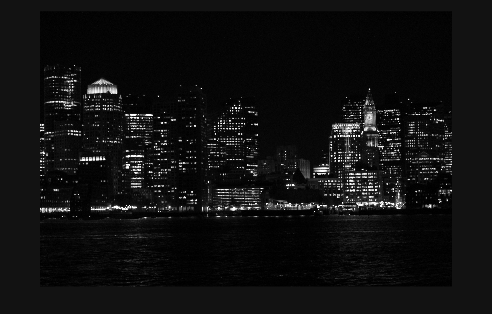

img = imread("boston night.jpg");
imgGray = im2gray(img);
imshow(imgGray)

Then, apply the gamma correction to the grayscale image

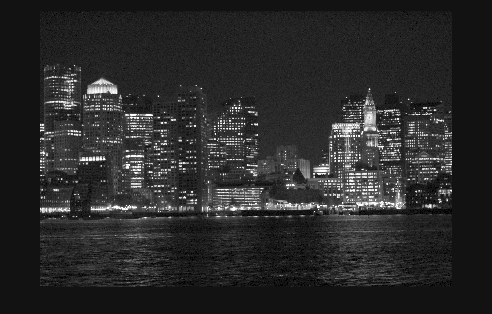

imgGamma = im2double(imgGray).^0.5;
imshow(imgGamma)

Finally, we apply the rotation and scale the image

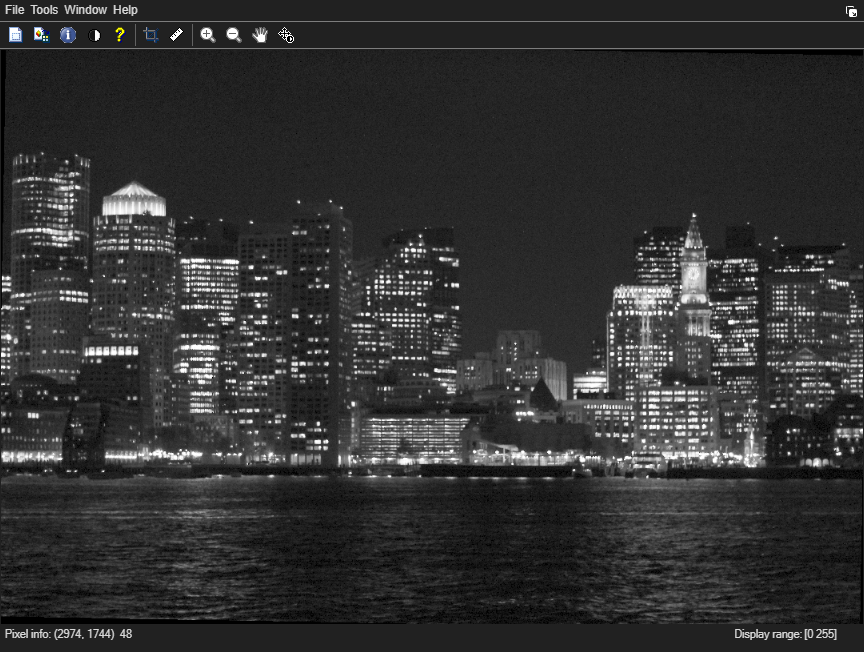

imgRotated = imrotate(imgGamma, -1, "crop");
imgAdjusted = im2uint8(imgRotated);
imtool(imgAdjusted)

diff = im2double(imgAdjusted) - im2double(imgGray)

diff =    -0.0078   -0.0039   -0.0118   -0.0235   -0.0157   -0.0078   -0.0039   -0.0078   -0.0157   -0.0157   -0.0157   -0.0118   -0.0039   -0.0039         0   -0.0039   -0.0078   -0.0078   -0.0118   -0.0157   -0.0118   -0.0118   -0.0118   -0.0078   -0.0078   -0.0078   -0.0118   -0.0118   -0.0039   -0.0078    0.1294    0.1137    0.1098    0.1137    0.1059    0.0902    0.0863    0.0902    0.0627    0.0588    0.0588    0.0510    0.0471    0.0941    0.0941    0.0784    0.1020    0.0824    0.0824    0.1216
   -0.0078   -0.0078   -0.0196   -0.0275   -0.0157   -0.0039   -0.0039   -0.0078   -0.0118   -0.0118   -0.0118   -0.0118   -0.0078   -0.0039         0         0   -0.0039   -0.0039   -0.0078   -0.0078   -0.0078   -0.0157   -0.0196   -0.0157   -0.0078   -0.0078   -0.0078   -0.0039         0         0    0.1294    0.1255    0.1294    0.1020    0.0627    0.0627    0.0902    0.0902    0.0627   -0.0039    0.0510    0.0745    0.0745    0.0471    0.0784    0.1020    0.1216    0.0824    0.0784  

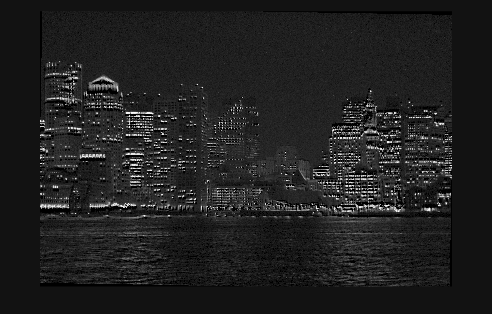

imshow(diff)

metadata = imfinfo("half moon.jpg");

camera = metadata.DigitalCamera

camera = struct with fields:
                ExposureTime: 0.0167
                     FNumber: 0
             ExposureProgram: 'Shutter priority'
             ISOSpeedRatings: 100
                 ExifVersion: [48 50 51 48]
            DateTimeOriginal: '2017:10:27 20:50:52'
           DateTimeDigitized: '2017:10:27 20:50:52'
     ComponentsConfiguration: 'YCbCr'
           ShutterSpeedValue: 6
               ApertureValue: 2.1475e+09
           ExposureBiasValue: 0
                MeteringMode: 'Pattern'
                       Flash: 'Flash did not fire, no strobe return detection function, compulsory flash suppression, flash function present, no red-eye reduction mode or unknown.'
                 FocalLength: 50
                   MakerNote: [27 0 1 0 3 0 49 0 0 0 180 4 0 0 2 0 3 0 4 0 0 0 22 5 0 0 4 0 3 0 34 0 0 0 30 5 0 0 6 0 2 0 19 0 0 0 98 5 0 0 7 0 2 0 23 0 0 0 118 5 0 0 9 0 2 0 1 0 0 0 0 0 0 0 16 0 4 0 1 0 0 0 4 4 0 128 25 0 3 0 1 0 0 0 … ] (1×4070 double)
                 Us